# Feature selection and classification for facial surface EMG data

#### Neurotechnology, Brains and Machines 2020

#### Sam Michalka 

This code will walk you through the organization and analysis of facial EMG data for classification of two conditions (though a very similar strategy could also be applied to EEG data and other data with sensors over time under different conditions). 

**The goal is to find features and a model to best classify the difference between smiling and frowning trials. ** 

This code includes:

- Loading and understanding the structure of the data (these are actually the same data as used in the last assignment, but now I'm giving you the data in a format commonly used for this type of analysis... a Matlab 'structure', which allow you to store all of the information about a dataset in one variable, helping to keep things clean and contained). 

- Doing additional preprocessing on the data by trying things like filtering or normalizing individual epochs

- Splitting the data into a training and testing set

- Extracting relevant features from the time series data

- Running classification on selected features for the training data

- Running classification on the testing data

## Load the data already preprocessed and epoched

These data have already been preprocessed a bit to clean them up and put them in a form that will make analysis easier (more on the details of this below). 

% Clear any variables in the workspace for a fresh start.
clear

% Load the data
load NeurotechsmilefrownangryblinkS1filt0p5notch56t64epochs.mat

We'll be working with EEG, but we're going to save this backup copy in originalEEG, so that you can have a comparison in case you get confused later when we're selecting a subset of the data.

originalEEG = EEG; %Store the original data in a structure so you can compare and make sure it worked


As a reminder, these are EMG data recorded while I made various facial expressions.  

The data for the zygomaticus major are channel 1 or *data_ch1*, and the data for the corrugator supercilii are channel 2 or *data_ch2*. I made a series of facial expressions. I chopped the data up into 409 trials or “epochs”. In each trial, I made a particular facial expression starting around the 0 millisecond mark (see EEG.*times* for timepoints in ms). There are 1000 points in each trial, representing 1000 measurements (one every 4 ms… or what is called a 250 Hz sampling rate).

The label tells you which facial expression I was attempting to make. These different labels are often referred to as different “conditions” of the experiment. Here’s a key:

A: angry… I clenched my jaw and furrowed my brow

B: blinking… I was just relaxed and blinking here (not all blinks are capture, but these are some examples)

F: frown… I tried to look sad and pout a little

S: smile… I smiled, just thinking about you learning to analyze this data… such joy

U: unstructured… this was intended to be some rest time, but should probably be ignored for now (something looks a little weird in it) 

For this analysis **we will focus on the comparison between smiling and frowning.**

## Understanding the EEG structure

Last time, I gave you the data in a few matrices and vectors. These are essentially the same data, but now stored in a Matlab 'structure' or 'struct' format. This format allows you to put different types of data in one place (making for some cleaner organization). 

You can explore the EEG structure by double clicking on the EEG variable in the Workspace, or by just typing EEG into the command window or in the code below (done for you).

EEG

EEG = struct with fields:
             setname: 'smilefrownblinksam filt epochs'
            filename: ''
            filepath: ''
             subject: ''
               group: ''
           condition: ''
             session: []
            comments: [2×39 char]
              nbchan: 2
              trials: 409
                pnts: 1000
               srate: 250
                xmin: -0.5000
                xmax: 3.4960
               times: [1×1000 double]
                data: [2×1000×409 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×2 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'common'
               event: [1×1746 struct]
             urevent: []
    eventdescription: {''  ''  ''  ''}
               epoch: [1×409 struct]
    epochdescription: {}
              reject: [1×1 struct]
               stats: [1×1 struct]
        

You can see that EEG is full of other variables of different shapes and sizes. Some of the important variables are shown here:

size(EEG.data) % EEG.data is the data, which is a 3d array: 2 channels X 1000 timepoints X 409 epochs or trials

ans =            2        1000         409


size(EEG.times) % times in milliseconds

ans =            1        1000


size(EEG.timessec) % times in seconds

ans =            1        1000


EEG.srate % This is the rate at which the data are sampled (250 Hz means 250 samples in 1 second of data).

ans = 250

Let's generate a plot of some of the data. This plots channel 1 data for the first 5 trials.

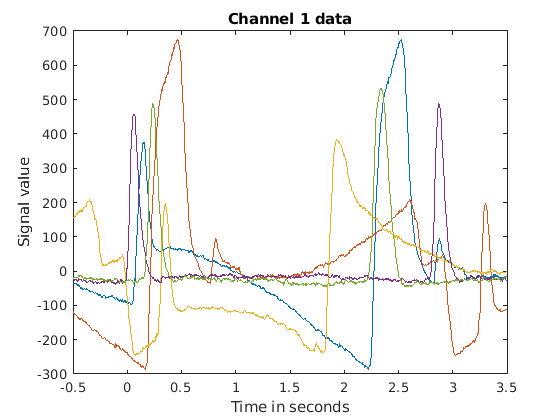

plot(EEG.timessec,squeeze(EEG.data(1,:,1:5))); 
xlabel('Time in seconds');ylabel('Signal value');title('Channel 1 data');

Notice that the time starts 500 ms before the "event" happens.

## Understand the event labels

EEG.epochlabelscat is a categorical variable that describes what event or condition happened during that epoch. These are the labels for classification.  Check out the description of the categories or labels at the beginning of this notebook. Since I pressed buttons to indicate what I was doing, the labels actually say 'F pressed' instead of just 'F'.

size(EEG.epochlabelscat) 

ans =      1   409


% You can use unique to see all the unique entries in a variable 
% Here, this is all the possible labels
availableeventlabels = unique(EEG.epochlabelscat)

availableeventlabels = 1×5 categorical array
     A pressed      B pressed      F pressed      S pressed      U pressed 


With categorical variables, you can use a == statement to find the cases where the epochs are of a certain type.

isequaltoFpressed = (EEG.epochlabelscat == 'F pressed');
sum(isequaltoFpressed) %this tells you how many epochs/trials are labeled as 'F pressed" or the "frown" condition

ans = 135

#### Exercise: Find the number of epochs (trials) for which the condition is "smile"

% Your code goes here
isequaltoSpressed = (EEG.epochlabelscat == 'S pressed');
sum(isequaltoSpressed)

ans = 151

Notice that the number of trials for these two conditions that we care about is different. This is called an imbalanced data set in machine learning.

## Remove data except for the two conditions that you want to compare

For this assignment, we'll only compare two conditions, so we will remove the rest of the data.

#### Exercise: Change this code to pick the same number of trials for each of the two conditions. Think about what this number should be to maximize the number of trials while balancing the data. You can fill in the actual number or write it more generally so it would work with new data.

num_trials_per_cond = min(sum(isequaltoFpressed), sum(isequaltoSpressed))

num_trials_per_cond = 135


% This vector in trial numbers of the data you want to keep.
% This code chooses the first "num_trials_per_cond" trials to keep. 
idx_trialstokeep = [find(EEG.epochlabelscat=="S pressed",num_trials_per_cond) find(EEG.epochlabelscat=="F pressed",num_trials_per_cond)]

idx_trialstokeep =      1     3     4     6     7    10    11    13    14    15    16    17    24    25    26    27    32    33    35    36    41    42    43    44    50    51    52    53    54    55    56    57    58    59    60    61    62    63    72    74    76    78    80    82    84    85    86    87    88    89


idx_trialstokeep = sort(idx_trialstokeep); % This line just puts the trials back in the order they occured.

Then we can update the variable EEG to only have the trials we want to include. 

Note: Normally we would do this indexing with EEG instead of orginalEEG, but I'm using this strategy to avoid the problems you will run into if you accidentally run this block of code multiple times.

EEG.data = originalEEG.data(:,:,idx_trialstokeep); %Trim the data
EEG.epochlabelscat = originalEEG.epochlabelscat(idx_trialstokeep); %Trim the list of labels
EEG.epochlabelscat = removecats(originalEEG.epochlabelscat(idx_trialstokeep)); %Remove extra categories
EEG.trials = sum(idx_trialstokeep);

Be sure to check that size of EEG.data and EEG.epochlabelscat are what you expect.

size(EEG.data)

ans =            2        1000         132


size(EEG.epochlabelscat)

ans =      1   132


## Preprocess the data

These data have already mostly been preprocessed for you using:

- a high pass filter at 0.5 Hz to remove drift

- a notch filter from 56 to 64 Hz to remove electrical noise at 60 Hz (this would be 50 Hz, if I were in Europe)

- epoching to chop the data up into 1000 timepoints or 4 seconds sampled at 250 samples per second (250 Hz sampling rate)

However, there are other preprocessing that is sometimes used for EMG data. You might remove the average signal from each trial (centering each trial around zero). Or you might choose to filter the data. 

#### Choose a preprocessing strategy (probably not both of these options). You can revisit the effects of these after doing the feature selection later. You'll need to uncomment some of the code or write your own. The examples here (currently commented out) show you how to remove the trial mean from each trial and how to do a high pass filter to remove frequencies below 20 Hz. Another option is to subtract the mean signal from -500 to 0 ms for a trial from the whole trial. If you want a challenge, you can write the code to do this (EEG.times is your friend).

This is done separately for each channel but for all the trials at once. If it's easier for you to understand, you can write this to loop through each trial as well as each channel (this will be slower, but it won't matter for this amount of data). 

for channel =1:size(EEG.data,1)
    
    % Trial by trial baseline removal
    EEG.data(channel,:, :) = EEG.data(channel,:, :) - mean(EEG.data(channel,:, :),2);
     
    % Do additional filtering of the data
%     HPfilterval = 20; % Value to high pass filter in Hz
%     EEG.data(channel,:, :) = highpass(squeeze(EEG.data(channel,:, :)),HPfilterval,EEG.srate);
end

## Split the data into a train and test set

Since we have a reasonable amount of data, we can split our data into a training and a test set. This helps us avoid overfitting our model to our data, especially as we start tuning parameters and trying out different features. 

We'll use the training set to tweak our model. We can actually do cross-validation or leave out some of the data within the training set to do internal testing.

At the very, very end (after we're settled on a model), then we can apply it to the test set. 

rng(101); % Do this to theoretically get the same split each time (not important for this situation, but important in my lab.)

% Hold out 20% of the data for the testing set.
ttpart = cvpartition(EEG.epochlabelscat,'HoldOut',.20);


% Set up table of data that includes the trial labels
traindata = table(EEG.epochlabelscat(ttpart.training)','VariableNames',{'labels'});

testdata = table(EEG.epochlabelscat(ttpart.test)','VariableNames',{'labels'});


Note that traindata and testdata only have the labels right now. We're going to add in the features below and put them in the same tables.

## Do feature extraction for selected trials

This is one to the two major parts of this analysis. This is the place where we take the time series data and extract important features for each trial.

You could just use the raw data in the classifier, but it will probably not work very well. Often the important features need to be extracted/ summarized from the time series data (signal over time). If it does work, it's probably due to overfitting, since the raw data will have a lot of time points which will each be independent features (so you might end up with ~1000 features, each one being a value at one point in time for each channel). However, it may be interesting to test this out for comparison. You can do this by setting the includedfeatures to be {'rawdata'}; there's a line to do this in a few blocks of code (you can just uncommented the line that says: %includedfeatures = {'rawdata'}; 

First, we'll want to set a few paramters. We probably want to include the data from both channels (1 and 2), so we can get the data from the eyebrow and cheek sensors, but it may be interesting to come back to this setting later and look at only one channel.


includedchannels = [1 2]; %channels to included, this will calculate features for each separately 


Set the time window to calculate parameters. The data are from -500 to 3496 ms. We might choose to use only a subset of this epoch, especially since it might not make sense to extract information from before the event happened (at 0 ms).

timewindowforfeatures = [0 200]; %start and stop in ms. If timepoints don't line up, this will select a slightly later time
timewindowepochidx = (find(EEG.times>=timewindowforfeatures(1),1)):(find(EEG.times>=timewindowforfeatures(2),1));



Now loop through and calculate all of the features based on the settings above and the code below.

Try adding some new features to improve the classifier (you can do this now or circle back to this if you're still trying to understandhow the code works). 

Here are some ideas for features to add (you can look these up in the Recognition of Emotion paper from last week or online resources):

- mean of the absolute value of the signal

- root mean square (RMS) 

- the variance of the signal

- integrated EMG (iEMG)

- simple squared integral (SSI)

- bandpower in different frequency bands (e.g., 64 to 110 Hz)

- other ideas that you come up with, you might look back at the plots from last week to think about how the smile and frown signals look different.

[Mithbavkar, Shraddha Atul, and Milind Shantilal Shah. "Recognition of Emotion Through Facial Expressions Using EMG Signal." 2019 International Conference on Nascent Technologies in Engineering (ICNTE). IEEE, 2019.](https://drive.google.com/file/d/1z2df6YGj-S1I4xbYPOcqUqHkP70LQFSM/view?usp=sharing)

***There are also existing Matlab functions for many of these (or parts of them), so you don't need to code the whole formula from scratch.***

Here is a suggested strategy for adding new features:

- Determine which feature to add (you can see the list above, look at a paper or online, or think of what might be relevant in this kind of data potentially inspired by plotting the data)

- Give your feature a name and add that name to the includedfeatures list below (e.g., 'var')

- Add a new "case" after the "switch" line in the code below. Give it the exact same name: case 'var'

- Calculate the value of the feature for each trial. You can do this in a loop, or you can do it all at once. The end result should be a vector or matrix that has the same number of rows as number of trials in your data (sum(ttpart.training)).

- Store this value in 'fvalues'

% List of all features to include in the data table. Even if others are
% listed below in the case format, they will be ignored unless they are
% listed here.
includedfeatures = {'mpv','mmav1'};

%includedfeatures = {'absmean','rms','iemg','ssi','mpv','var','bp2t20','bp20t40','bp40t56','bp64t110','mmav1'};


% You can run this version to just use the raw data, which is not a very good feature, but worth checking out to see how well it does. This probably overfits, so you might want to add downsampling.
%includedfeatures = {'rawdata'}; 


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Loop through all desired features and put into data table
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Loop through and do this once for the training and once for the test data
% (so they get treated the same way, but are kept separate)
for ttround = 1:2 
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Configure things to do training data on the first round and the test
    % data on the second round. You can mostly ignore this and assume it
    % works.
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    if ttround == 1
        %Do training data first
        tempdata = traindata;
        idxt = ttpart.training;
    elseif ttround == 2
        % Do the test data on the second loop
        tempdata = testdata;
        idxt = ttpart.test;
    end
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Add features to the data table
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    % Loop through each channel
    for ch = includedchannels 
        
        % To simplify things, we'll assign the raw data to an array. (This
        % is slightly slower and worse for memory, but much easier to read)
        % mydata will be a num timepoints X num trials matrix 
        clear mydata;
        mydata = squeeze(EEG.data(ch,timewindowepochidx,idxt));
        
        
        % Loop through each feature that you want to include by name
        for f = 1:length(includedfeatures)
            
            % We'll use fvalues to temporarily store the vector or matrix
            % of a particular feature of interest. There are other ways to
            % do this, but this setup allows you to loop through options in
            % a consistent way
            fvalues =[]; %clear and initialize fvalues
            
            currentfeature = includedfeatures{f};
            fprintf(strcat('Analysing - ', currentfeature, ' - for channel - ' , num2str(ch),' now. \n'))
            
            % We can use switch and case to find the code for the feature
            % whose name matches currentfeature
            switch currentfeature 
          
                case 'mpv'
                    fvalues = max(mydata);
                
                case 'bp20t40' %bandpower between 20 and 40 Hz                       
                    fvalues = bandpower(mydata,EEG.srate,[20 40])';
                    
               case 'mmav1'
                    low = prctile(mydata,25,1);
                    high = prctile(mydata,75,1);
                    weightedVals = mydata; 
                    weightedVals(weightedVals < low) = weightedVals(weightedVals < low)*.5;
                    weightedVals(weightedVals > high) = weightedVals(weightedVals > high)*.5;
                    fvalues = mean(abs(weightedVals));
                    
                case 'rawdata'
                    fvalues = mydata'; %this is just the raw data
                    
                otherwise
                    disp(strcat('unknown feature: ', includedfeatures{f},', skipping....'))
                
            end
            
            
            % Make sure fvalues is the right shape and put it into the
            % feature table if you can. Otherwise, post a warning and skip
            % it. You can ignore this code.
            if isempty(fvalues)
                % if it's empty, skip all of this
            elseif size(squeeze(fvalues),1) ~= sum(idxt) %if the size is wrong, see if you can fix it
                if size(fvalues,2) == sum(idxt)
                    % If you just need to transpose your data to make it
                    % fit, do so here
                    fvalues = fvalues';
                    eval(['tempdata.FEAT_ch' num2str(ch) '_' includedfeatures{f} ' = fvalues;']);
                else         
                    warning(strcat('fvalues does not fit in data table, skipping feature: ', includedfeatures{f},...
                        '. _  Please fix the code to align shapes. Num trials: ',num2str(sum(idxt)),...
                        ' and size fvalues : ',num2str(size(fvalues))))
                end
            else 

                % Put fvalues into the datatable with appropriate feature name
                % Using the 'eval' function is a really fancy want to make
                % the variable names in the table match the fvalues that
                % you put in. Otherwise, you just need to keep track of
                % which feature you stored in which row, but that requires
                % a lot of organization and can lead to mistakes. 
                % Don't worry too much about how this works, just
                % understand that what it is doing is putting the numbers
                % in fvalues into an appropriately named variable in the
                % data 
                eval(['tempdata.FEAT_ch' num2str(ch) '_' includedfeatures{f} ' = fvalues;']);
            end
        end
    end

    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Configure things to do training data on the first round and the test
    % data on the second round. You can mostly ignore this and assume it
    % works.
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    if ttround == 1
        % Put the tempdata into the traindata variable (if this is the
        % first time through)
        traindata = tempdata;
        traindata = splitvars(traindata); %split subvariables into independent variable to not anger the classifier. You really only need this is some of your feature varialbes above are not vectors, but it doesn't hurt to run this line.
        clear tempdata;
    elseif ttround == 2
        % Put the tempdata into the testdata table if it's the second time
        % through 
        testdata = tempdata;
        testdata = splitvars(testdata);
        clear tempdata;
    end
    
end

Analysing -mpv - for channel -1 now. 
Analysing -mmav1 - for channel -1 now. 
Analysing -mpv - for channel -2 now. 
Analysing -mmav1 - for channel -2 now. 
Analysing -mpv - for channel -1 now. 
Analysing -mmav1 - for channel -1 now. 
Analysing -mpv - for channel -2 now. 
Analysing -mmav1 - for channel -2 now. 


## Understand the format of the traindata

You can start by viewing the first few rows of the data using the head() function.

head(traindata)

ans = 8×5 table
     labels      FEAT_ch1_mpv    FEAT_ch1_mmav1    FEAT_ch2_mpv    FEAT_ch2_mmav1
    _________    ____________    ______________    ____________    ______________

    B pressed       368.81           130.35           9.1707           44.044    
    B pressed      -70.835           137.52           63.346           40.272    
    B pressed       241.17           27.005           12.857           4.9247    
    B pressed        6.284           18.855           10.432           3.7019    
    S pressed      -14.657           16.906           1.3903           4.6657    
    B pressed       386.23           79.892           38.121           19.278    
    F pressed      -671.14           495.97          -83.246           73.971    
    S pressed       48.598            7.403          -0.1617            29.

Now, you can make some plots showing 2 features on different axes with colors representing the labels.

Here are the names of the features:

traindata.Properties.VariableNames'

ans = 5×1 cell array
    {'labels'        }
    {'FEAT_ch1_mpv'  }
    {'FEAT_ch1_mmav1'}
    {'FEAT_ch2_mpv'  }
    {'FEAT_ch2_mmav1'}


Here is some example code, which you can use to explore some other features.

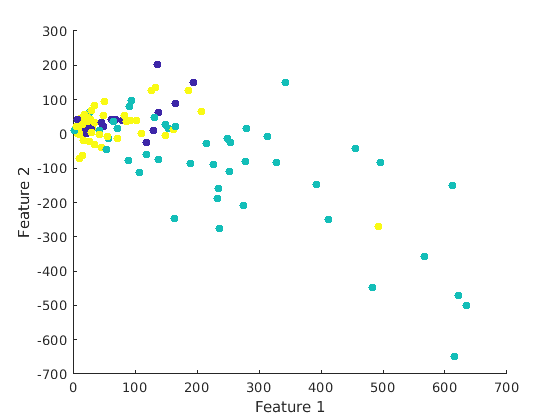

figure; 
scatter(traindata.FEAT_ch1_mmav1,traindata.FEAT_ch2_mpv,36,traindata.labels,'filled')
xlabel('Feature 1'); ylabel('Feature 2'); 

## Decision point: stay with code or open the Classification Learner app

Now you have a choice:

1) You can keep going in the purely code version of this. If you want to do that, skip ahead to the next section.

2) You can use the Classification Learner App that we used in Assignment #5 to explore different machine learning models. The app allows you to do more clicking and less coding. You can refer back to the resources in assignment 5. 

- You an open the Classification Learner App by either running a line of code that says: classificationLearner or you can click on the APPS ribbon at the top of Matlab and find the Classification Learner app.

- Use New Session and then load the traindata from the workspace variable option. 

- After you've tested some models you can export one that you like. There is also code at the very bottom to help you run a model on the testdata.

classificationLearner

## Setup and run classification on the training data (using code)

This code sets up and runs the classification on the traindata. 

% Predictors are features (sometimes matlab uses the word predictors
% instead, so we're matching their language (which will make looking up
% help easier).

% Select the variables that are not the labels.
predictorNames = traindata.Properties.VariableNames(2:end); %This selects all but first (assumed to be labels and orig index number, fix if this is not the case, or you can manually select here)
predictors = traindata(:,predictorNames); %This is the data for these predictorNames
% Note: you could use a different version of predictorNames to choose a
% subset of the features.


% Response is the labels, just putting this in a separate variable to match
% the matlab documentation
response = traindata(:,'labels'); %labels


% This is the code that sets up the SVM classifier
trainedClassifier = fitcsvm(predictors, ...
    response, ...
    'KernelFunction', 'Linear', ...
    'Standardize',false...  
     );  % 

Error using ClassificationSVM.prepareData (line 652)
Use fitcecoc to train a linear model with more than 2 classes.

Error in classreg.learning.FitTemplate/fit (line 218)
                    this.PrepareData(X,Y,this.BaseFitObjectArgs{:});

Error in 

The lines above build the classifier. You can look up the different parameters you can put into the fitcsvm function, these include things like: 'OutlierFraction',0.10,...

Or you might want to look up other classifiers besides SVM to use here. Matlab has lots of options, which have different parameters, but tend to take in the same form of predictors and response variables.

The next part sets up cross-validation. Look this up (this is commonly used in machine learning).

% k-fold cross validation
kval = 5; %Choose number of folds. You can also just set this manually.
cpart = cvpartition(response{:,1},'KFold',kval); % k-fold stratified cross validation
partitionedModel = crossval(trainedClassifier,'CVPartition',cpart);

% Make predictions of the crossfold validation predicted based on the
% traindata
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);
     
% Cross validation output
validationAccuracy = 1 - kfoldLoss(partitionedModel);
fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy*100);
trainconchart = confusionchart(traindata.labels,validationPredictions);

trainconchartNorm = confusionchart(traindata.labels,validationPredictions,'Normalization','row-normalized');

## Tune the parameters of the classifier based on the training data.

Congrats, you have worked through the entire classification process for time series data using the training data:

preprocessing -> feature extraction -> feature selection (all) -> classification

You can now go back and play around with different parameters to see how they affect the classification accuracy (or the confusion matrix, if you want to get fancy). There are a lot of parameters that you could change (see the bulleted list below). 

#### Try out some different parameters, and record the results of different configurations that you tried and how they affected the cross-validation accuracy. 

You might record this in the notes here or in a spreadsheet with columns like:

- Preprocessing strategy

- Included channels

- Time window for extracting features

- Included features

- Classifier type (e.g., SVM, LDA, Decision Tree, etc)

- Classifier parameters (e.g., linear kernel, removing 5% of outliers, etc)

- Classification accuracy (or % correct in each category)

Since there a so many things to change, it's important to keep track of what parameters you use. 

You can also think about tuning a particular parameter in a regimented way. For example, I might choose to look at 5 different time window, all starting at 0 ms to see how including a larger time window affects accuracy (a larger time window means more data gets included, but this also means that my time window might start including data from after I stopped smiling/frowning or even started making a different face).

If you look at a parameter in an organized way (holding everything else constant), then you can make a graph of time window vs accuracy to see how changing the time window affects accuracy. (You can even get fancy and do this in a loop if you want (but it will be a really big loop).

## When you're done tuning, then run a final analysis on the testing data


% Code for prediction of test data 
[predictedlabel,score] = predict(trainedClassifier,testdata(:,predictorNames));

Check for missing argument or incorrect argument data type in call to function 'predict'.


testAccuracy = sum(testdata.labels==predictedlabel)./length(testdata.labels);
fprintf('\nTest accuracy = %.2f%%\n', testAccuracy*100);
testconchart = confusionchart(testdata.labels,predictedlabel);
testconchartNorm = confusionchart(testdata.labels,predictedlabel,'Normalization','row-normalized');

#### How does the classifier you chose do on the training data compared to the testing data? Based on this, do you think that you overfit your model or found a nice set of parameters? (You should expect to see a small/moderate decrease in accuracy for the test data even if your model is a good fit). 